# REPRESENTACIÓN DE PROPIEDADES DE SOFA

## OBTENCIÓN DE DATOS DE SOFA

% Cargamos los datos desde un archivo dado que el tiempo de simulación es
% muy alto
% load("matlab.mat");

% Desglosamos los valores en sus respectivas componentes
[vector_tiempo_4_5,posiciones_nodo_0_4_5,posiciones_nodo_0_4_5_y,posiciones_nodo_0_4_5_z] = readvars('properties_0-28-56_4.5_x.txt');
[vector_tiempo_5,posiciones_nodo_0_5,posiciones_nodo_0_5_y,posiciones_nodo_0_5_z] = readvars('properties_0-28-56_5_x.txt');
[vector_tiempo_5_5,posiciones_nodo_0_5_5,posiciones_nodo_0_5_5_y,posiciones_nodo_0_5_5_z] = readvars('properties_0-28-56_5.5_x.txt');
[vector_tiempo_5_8,posiciones_nodo_0_5_8,posiciones_nodo_0_5_8_y,posiciones_nodo_0_5_8_z] = readvars('properties_0-28-56_5.8_x.txt');
[vector_tiempo_6,posiciones_nodo_0_6,posiciones_nodo_0_6_y,posiciones_nodo_0_6_z] = readvars('properties_0-28-56_6_x.txt');
[vector_tiempo_6_2,posiciones_nodo_0_6_2,posiciones_nodo_0_6_2_y,posiciones_nodo_0_6_2_z] = readvars('properties_0-28-56_6.2_x.txt');
[vector_tiempo_6_4,posiciones_nodo_0_6_4,posiciones_nodo_0_6_4_y,posiciones_nodo_0_6_4_z] = readvars('properties_0-28-56_6.4_x.txt');
[vector_tiempo_6_5,posiciones_nodo_0_6_5,posiciones_nodo_0_6_5_y,posiciones_nodo_0_6_5_z] = readvars('properties_0-28-56_6.5_x.txt');
[vector_tiempo_7,posiciones_nodo_0_7,posiciones_nodo_0_7_y,posiciones_nodo_0_7_z] = readvars('properties_0-28-56_7_x.txt');
[vector_tiempo_7_5,posiciones_nodo_0_7_5,posiciones_nodo_0_7_5_y,posiciones_nodo_0_7_5_z] = readvars('properties_0-28-56_7.5_x.txt');
[vector_tiempo_7_2,posiciones_nodo_0_7_2,posiciones_nodo_0_7_2_y,posiciones_nodo_0_7_2_z] = readvars('properties_0-28-56_7.2_x.txt');
[vector_tiempo_7_4,posiciones_nodo_0_7_4,posiciones_nodo_0_7_4_y,posiciones_nodo_0_7_4_z] = readvars('properties_0-28-56_7.4_x.txt');
[vector_tiempo_7_8,posiciones_nodo_0_7_8,posiciones_nodo_0_7_8_y,posiciones_nodo_0_7_8_z] = readvars('properties_0-28-56_7.8_x.txt');

## HALLAMOS EL VALOR MÁXIMO Y MÍNIMO DE DESPLAZAMIENTO

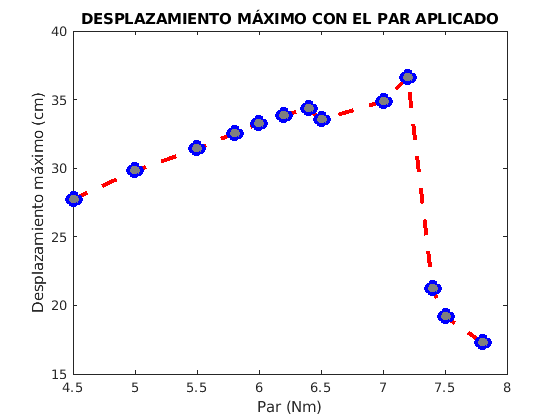

% Todas las posiciones están en metros, salvo la última sentencia

% Concatenamos los vectores del tiempo y las posiciones recogidas de los
% nodos estudiados para detectar dónde se encuentra el máximo y el mínimo
posicion_0_4_5_ = [vector_tiempo_4_5 posiciones_nodo_0_4_5 posiciones_nodo_0_4_5_y posiciones_nodo_0_4_5_z];

posicion_0_5_ = [vector_tiempo_5 posiciones_nodo_0_5 posiciones_nodo_0_5_y posiciones_nodo_0_5_z];

posicion_0_5_5_ = [vector_tiempo_5_5 posiciones_nodo_0_5_5 posiciones_nodo_0_5_5_y posiciones_nodo_0_5_5_z] ;

posicion_0_5_8_ = [vector_tiempo_5_8 posiciones_nodo_0_5_8 posiciones_nodo_0_5_8_y posiciones_nodo_0_5_8_z];

posicion_0_6_ = [vector_tiempo_6 posiciones_nodo_0_6 posiciones_nodo_0_6_y posiciones_nodo_0_6_z];

posicion_0_6_2_ = [vector_tiempo_6_2 posiciones_nodo_0_6_2 posiciones_nodo_0_6_2_y posiciones_nodo_0_6_2_z];

posicion_0_6_4_ = [vector_tiempo_6_4 posiciones_nodo_0_6_4 posiciones_nodo_0_6_4_y posiciones_nodo_0_6_4_z];

posicion_0_6_5_ = [vector_tiempo_6_5 posiciones_nodo_0_6_5 posiciones_nodo_0_6_5_y posiciones_nodo_0_6_5_z];

posicion_0_7_ = [vector_tiempo_7 posiciones_nodo_0_7 posiciones_nodo_0_7_y posiciones_nodo_0_7_z];

posicion_0_7_5_ = [vector_tiempo_7_5 posiciones_nodo_0_7_5 posiciones_nodo_0_7_5_y posiciones_nodo_0_7_5_z];

posicion_0_7_2_ = [vector_tiempo_7_2 posiciones_nodo_0_7_2 posiciones_nodo_0_7_2_y posiciones_nodo_0_7_2_z];

posicion_0_7_4_ = [vector_tiempo_7_4 posiciones_nodo_0_7_4 posiciones_nodo_0_7_4_y posiciones_nodo_0_7_4_z];

posicion_0_7_8_ = [vector_tiempo_7_8 posiciones_nodo_0_7_8 posiciones_nodo_0_7_8_y posiciones_nodo_0_7_8_z];

% Obtenemos el máximo y mínimo de los tres nodos
M_0_4_5 = max(posicion_0_4_5_(:,4));
m_0_4_5 = min(posicion_0_4_5_(:,4));

M_0_5 = max(posicion_0_5_(:,4));
m_0_5 = min(posicion_0_5_(:,4));

M_0_5_5 = max(posicion_0_5_5_(:,4));
m_0_5_5 = min(posicion_0_5_5_(:,4));

M_0_5_8 = max(posicion_0_5_8_(:,4));
m_0_5_8 = min(posicion_0_5_8_(:,4));

M_0_6 = max(posicion_0_6_(:,4));
m_0_6 = min(posicion_0_6_(:,4));

M_0_6_2 = max(posicion_0_6_2_(:,4));
m_0_6_2 = min(posicion_0_6_2_(:,4));

M_0_6_4 = max(posicion_0_6_4_(:,4));
m_0_6_4 = min(posicion_0_6_4_(:,4));

M_0_6_5 = max(posicion_0_6_5_(:,4));
m_0_6_5 = min(posicion_0_6_5_(:,4));

M_0_7 = max(posicion_0_7_(:,4));
m_0_7 = min(posicion_0_7_(:,4));

M_0_7_5 = max(posicion_0_7_5_(:,4));
m_0_7_5 = min(posicion_0_7_5_(:,4));

M_0_7_2 = max(posicion_0_7_2_(:,4));
m_0_7_2 = min(posicion_0_7_2_(:,4));

M_0_7_4 = max(posicion_0_7_4_(:,4));
m_0_7_4 = min(posicion_0_7_4_(:,4));

M_0_7_8 = max(posicion_0_7_8_(:,4));
m_0_7_8 = min(posicion_0_7_8_(:,4));

% Detectamos el tiempo para el cual se ha alcanzado el mínimo y lo
% guardamos en una variable auxiliar
for i=1:length(posicion_0_4_5_)
    if (m_0_4_5==posicion_0_4_5_(i,4))

        tiempo_0_4_5 = posicion_0_4_5_(i,1);
    end
end

for i=1:length(posicion_0_5_)
    if (m_0_5==posicion_0_5_(i,4))

        tiempo_0_5 = posicion_0_5_(i,1);
    end
end

for i=1:length(posicion_0_5_5_)
    if (m_0_5_5==posicion_0_5_5_(i,4))

        tiempo_0_5_5 = posicion_0_5_5_(i,1);
    end
end

for i=1:length(posicion_0_5_8_)
    if (m_0_5_8==posicion_0_5_8_(i,4))

        tiempo_0_5_8 = posicion_0_5_8_(i,1);
    end
end

for i=1:length(posicion_0_6_)
    if (m_0_6==posicion_0_6_(i,4))

        tiempo_0_6 = posicion_0_6_(i,1);
    end
end

for i=1:length(posicion_0_6_2_)
    if (m_0_6_2==posicion_0_6_2_(i,4))

        tiempo_0_6_2 = posicion_0_6_2_(i,1);
    end
end

for i=1:length(posicion_0_6_4_)
    if (m_0_6_4==posicion_0_6_4_(i,4))

        tiempo_0_6_4 = posicion_0_6_4_(i,1);
    end
end

for i=1:length(posicion_0_6_5_)
    if (m_0_6_5==posicion_0_6_5_(i,4))

        tiempo_0_6_5 = posicion_0_6_5_(i,1);
    end
end

for i=1:length(posicion_0_7_)
    if (m_0_7==posicion_0_7_(i,4))

        tiempo_0_7 = posicion_0_7_(i,1);
    end
end

for i=1:length(posicion_0_7_5_)
    if (m_0_7_5==posicion_0_7_5_(i,4))

        tiempo_0_7_5 = posicion_0_7_5_(i,1);
    end
end

for i=1:length(posicion_0_7_2_)
    if (m_0_7_2==posicion_0_7_2_(i,4))

        tiempo_0_7_2 = posicion_0_7_2_(i,1);
    end
end

for i=1:length(posicion_0_7_4_)
    if (m_0_7_4==posicion_0_7_4_(i,4))

        tiempo_0_7_4 = posicion_0_7_4_(i,1);
    end
end

for i=1:length(posicion_0_7_8_)
    if (m_0_7_8==posicion_0_7_8_(i,4))

        tiempo_0_7_8 = posicion_0_7_8_(i,1);
    end
end

% Una vez con dicha posición del nodo central, podemos obtener de una
% manera más precisa cuál es el desplazamiento máximo, medido como la
% distancia que hay del nodo central a ambos puntos extremos de la barra
% Unidades en cm
desplazamiento_real_derecho_4_5 = (abs(m_0_4_5))*100;

desplazamiento_real_derecho_5 = (abs(m_0_5))*100;

desplazamiento_real_derecho_5_5 = (abs(m_0_5_5))*100;

desplazamiento_real_derecho_5_8 = (abs(m_0_5_8))*100;

desplazamiento_real_derecho_6 = (abs(m_0_6))*100;

desplazamiento_real_derecho_6_2 = (abs(m_0_6_2))*100;

desplazamiento_real_derecho_6_4 = (abs(m_0_6_4))*100;

desplazamiento_real_derecho_6_5 = (abs(m_0_6_5))*100;

desplazamiento_real_derecho_7 = (abs(m_0_7))*100;

desplazamiento_real_derecho_7_5 = (abs(m_0_7_5))*100;

desplazamiento_real_derecho_7_2 = (abs(m_0_7_2))*100;

desplazamiento_real_derecho_7_4 = (abs(m_0_7_4))*100;

desplazamiento_real_derecho_7_8 = (abs(m_0_7_8))*100;

% Almacenamos el valor a mano de las frecuencias estudiadas en SOFA
pares = [4.5 5 5.5 5.8 6 6.2 6.4 6.5 7 7.2 7.4 7.5 7.8];
frecuencias = [18.48 19.04];
% Almacenamos el valor de los DESPLAZAMIENTO obtenidos
desp = [desplazamiento_real_derecho_4_5 desplazamiento_real_derecho_5 desplazamiento_real_derecho_5_5 desplazamiento_real_derecho_5_8 desplazamiento_real_derecho_6 desplazamiento_real_derecho_6_2 desplazamiento_real_derecho_6_4 desplazamiento_real_derecho_6_5 desplazamiento_real_derecho_7 desplazamiento_real_derecho_7_2 desplazamiento_real_derecho_7_4 desplazamiento_real_derecho_7_5 desplazamiento_real_derecho_7_8];

% Representamos dichos valores de DESPLAZAMIENTO con la frecuencia
% plot(frecuencias,desp,'--bo',...
%     'LineWidth',3,...
%     'MarkerSize',10,...
%     'MarkerEdgeColor','b',...
%     'MarkerFaceColor',[0.5,0.5,0.5]);
% title('DESPLAZAMIENTO MÁXIMOS CON LA FRECUENCIA')
% xlabel('Frecuencia (rad/s)') 
% ylabel('Desplazamiento máximo (cm)')

% Representamos dichos valores de DESPLAZAMIENTO con el par
plot(pares,desp,'--ro',...
    'LineWidth',3,...
    'MarkerSize',10,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5]);
title('DESPLAZAMIENTO MÁXIMO CON EL PAR APLICADO')
xlabel('Par (Nm)') 
ylabel('Desplazamiento máximo (cm)')

## REPRESENTACIÓN 3D DE LOS DESPLAZAMIENTO DEL NODO A LAS FRECUENCIAS ESTUDIADAS

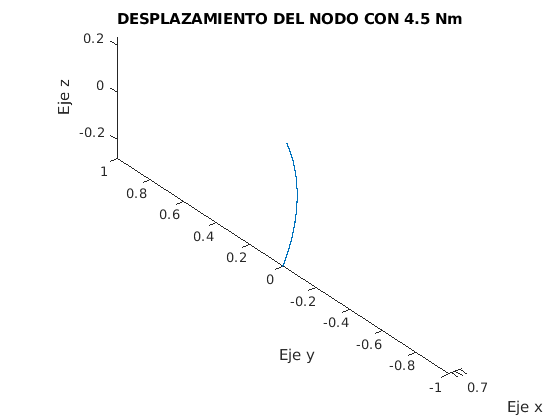

% Obtenemos una representación gráfica con los valores de X,Y y Z de los 3 nodos
% estudiados de la barra

% Realizar para cada simulatiom step para mostrar las diferencias

plot3(posicion_0_4_5_(:,2),posicion_0_4_5_(:,3),posicion_0_4_5_(:,4))
title('DESPLAZAMIENTO DEL NODO CON 4.5 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal

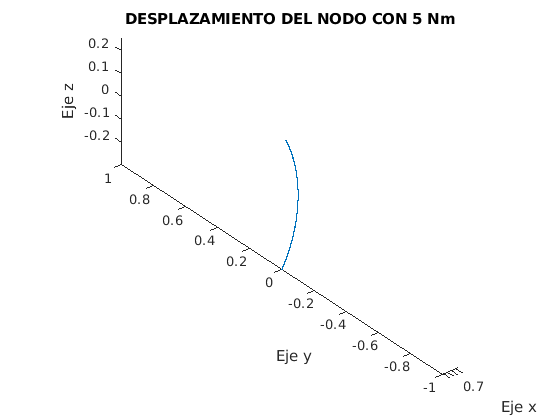


plot3(posicion_0_5_(:,2),posicion_0_5_(:,3),posicion_0_5_(:,4))
title('DESPLAZAMIENTO DEL NODO CON 5 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal

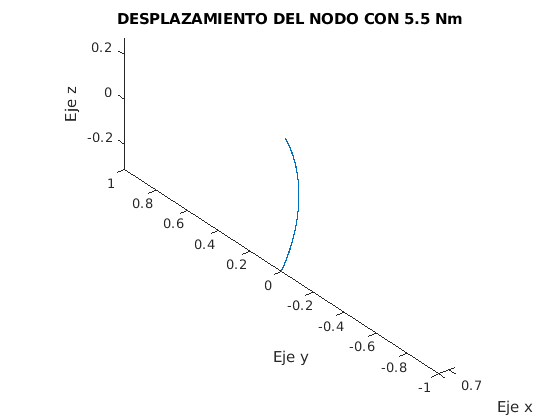


plot3(posicion_0_5_5_(:,2),posicion_0_5_5_(:,3),posicion_0_5_5_(:,4))
title('DESPLAZAMIENTO DEL NODO CON 5.5 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal

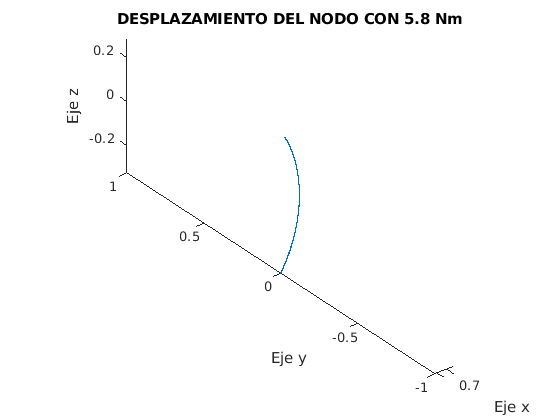


plot3(posicion_0_5_8_(:,2),posicion_0_5_8_(:,3),posicion_0_5_8_(:,4))
title('DESPLAZAMIENTO DEL NODO CON 5.8 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal

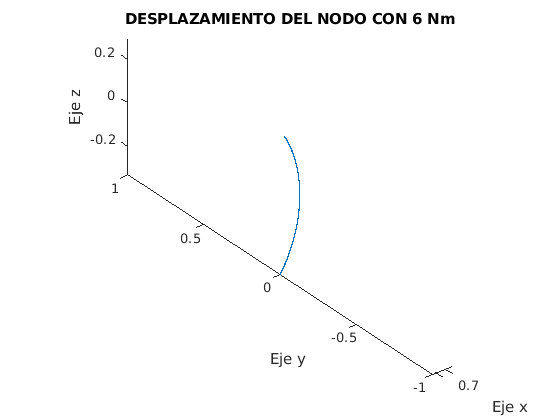


plot3(posicion_0_6_(:,2),posicion_0_6_(:,3),posicion_0_6_(:,4))
title('DESPLAZAMIENTO DEL NODO CON 6 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal

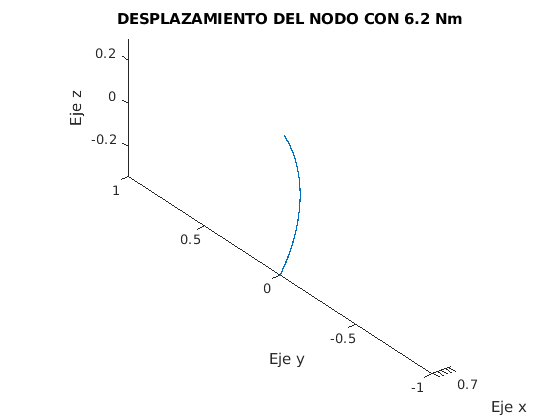


plot3(posicion_0_6_2_(:,2),posicion_0_6_2_(:,3),posicion_0_6_2_(:,4))
title('DESPLAZAMIENTO DEL NODO CON 6.2 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal

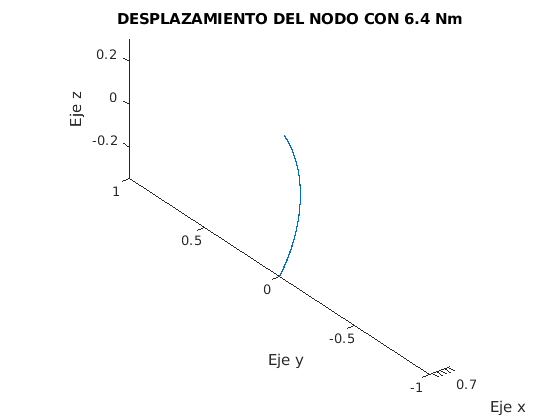


plot3(posicion_0_6_4_(:,2),posicion_0_6_4_(:,3),posicion_0_6_4_(:,4))
title('DESPLAZAMIENTO DEL NODO CON 6.4 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal

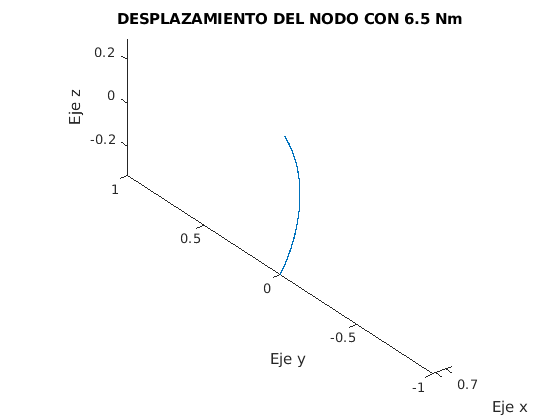


plot3(posicion_0_6_5_(:,2),posicion_0_6_5_(:,3),posicion_0_6_5_(:,4))
title('DESPLAZAMIENTO DEL NODO CON 6.5 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal

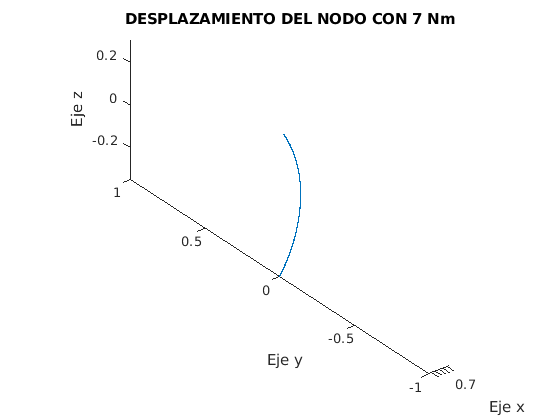


plot3(posicion_0_7_(:,2),posicion_0_7_(:,3),posicion_0_7_(:,4))
title('DESPLAZAMIENTO DEL NODO CON 7 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal

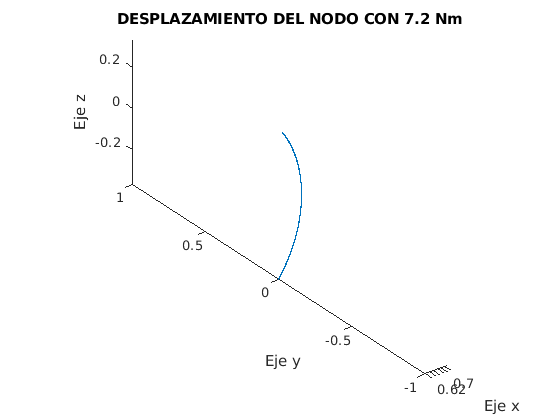


plot3(posicion_0_7_2_(:,2),posicion_0_7_2_(:,3),posicion_0_7_2_(:,4))
title('DESPLAZAMIENTO DEL NODO CON 7.2 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal

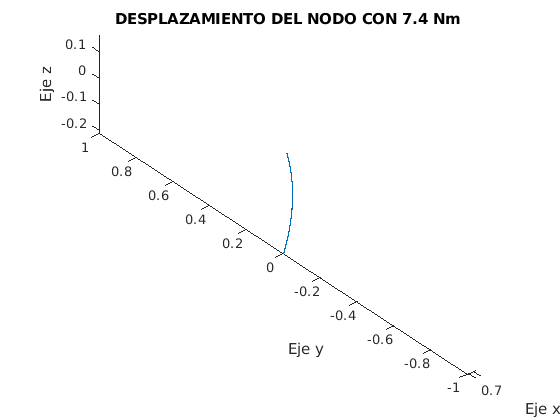


plot3(posicion_0_7_4_(:,2),posicion_0_7_4_(:,3),posicion_0_7_4_(:,4))
title('DESPLAZAMIENTO DEL NODO CON 7.4 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal

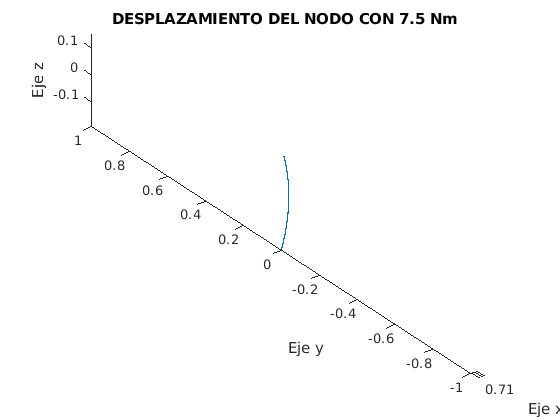


plot3(posicion_0_7_5_(:,2),posicion_0_7_5_(:,3),posicion_0_7_5_(:,4))
title('DESPLAZAMIENTO DEL NODO CON 7.5 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal

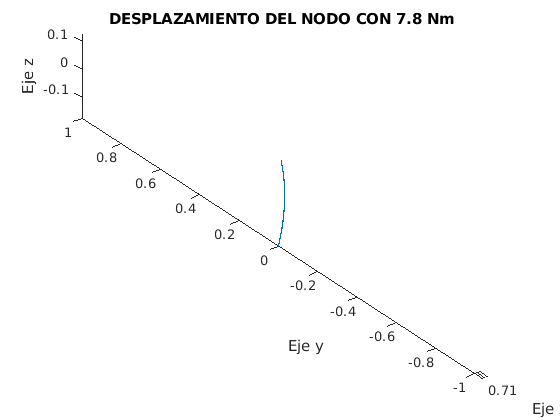


plot3(posicion_0_7_8_(:,2),posicion_0_7_8_(:,3),posicion_0_7_8_(:,4))
title('DESPLAZAMIENTO DEL NODO CON 7.8 Nm')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal

## REPRESENTACIÓN DE ENERGÍA CINÉTICA PARA TODAS LAS FRECUENCIAS

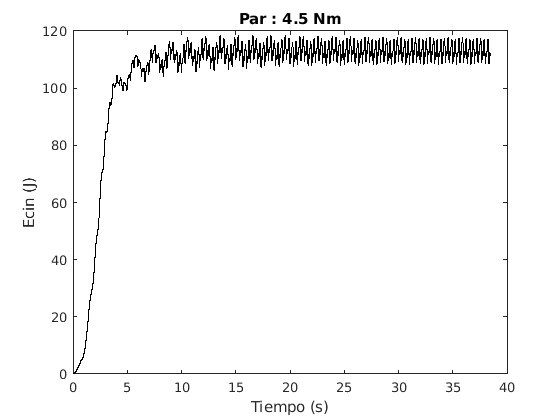

% Leemos los archivos procedentes de SOFA con los datos de energía cinética
% para las distintas frecuencias.
[vector_tiempo5,Ecin5] = readvars('Energy_4.5_wcin.txt');
[vector_tiempo1,Ecin1] = readvars('Energy_5.5_wcin.txt');
[vector_tiempo2,Ecin2] = readvars('Energy_5_wcin.txt');
[vector_tiempo6,Ecin6] = readvars('Energy_7_wcin.txt');
[vector_tiempo3,Ecin3] = readvars('Energy_6_wcin.txt');
[vector_tiempo9,Ecin9] = readvars('Energy_6.2_wcin.txt');
[vector_tiempo8,Ecin8] = readvars('Energy_6.4_wcin.txt');
[vector_tiempo4,Ecin4] = readvars('Energy_6.5_wcin.txt');
[vector_tiempo7,Ecin7] = readvars('Energy_7.5_wcin.txt');
[vector_tiempo11,Ecin11] = readvars('Energy_7.2_wcin.txt');
[vector_tiempo12,Ecin12] = readvars('Energy_7.4_wcin.txt');
[vector_tiempo13,Ecin13] = readvars('Energy_7.8_wcin.txt');
[vector_tiempo10,Ecin10] = readvars('Energy_5.8_wcin.txt');

% Realizamos las representación de las distintas energías para cada
% frecuencia estudiada
plot(vector_tiempo5,Ecin5,'k')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 4.5 Nm')

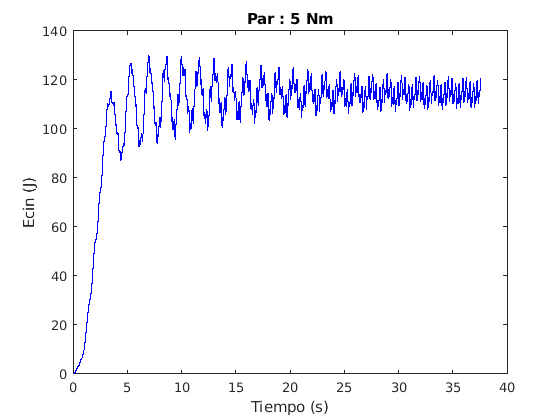

plot(vector_tiempo2,Ecin2,'b')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 5 Nm')

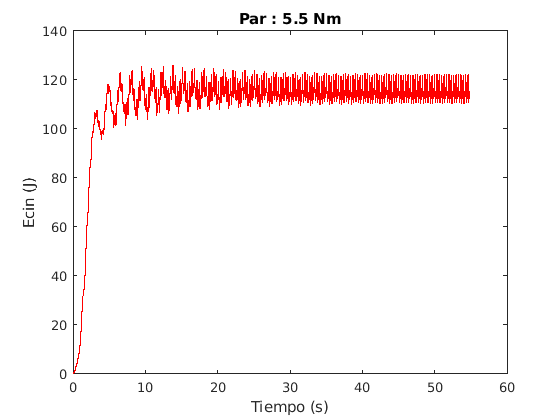

plot(vector_tiempo1,Ecin1,'r')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 5.5 Nm')

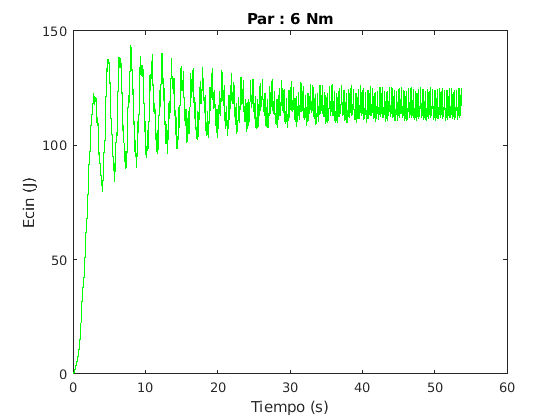

plot(vector_tiempo3,Ecin3,'g')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 6 Nm')

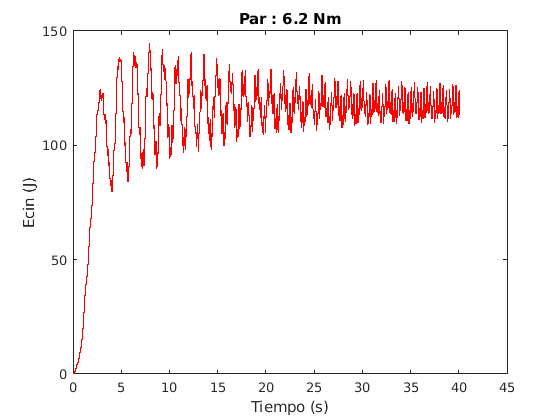

plot(vector_tiempo9,Ecin9,'r')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 6.2 Nm')

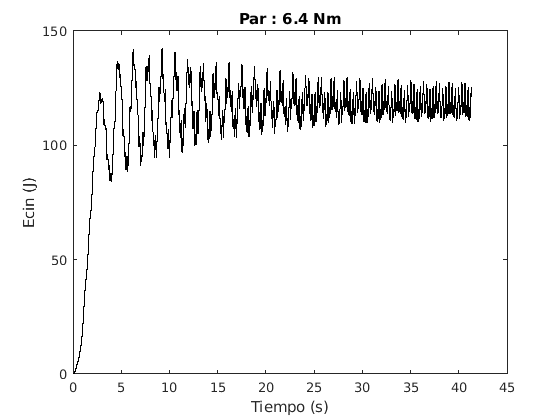

plot(vector_tiempo8,Ecin8,'k')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 6.4 Nm')

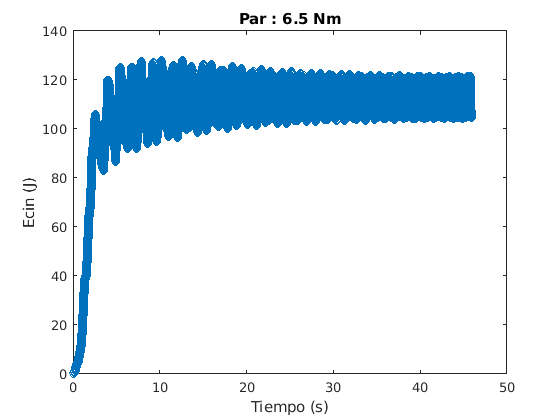

plot(vector_tiempo4,Ecin4,'o')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 6.5 Nm')

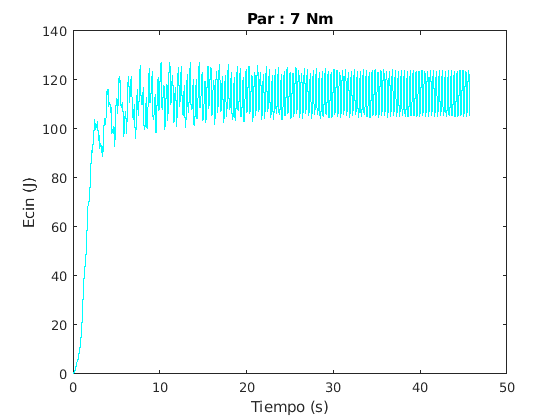

plot(vector_tiempo6,Ecin6,'c')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 7 Nm')

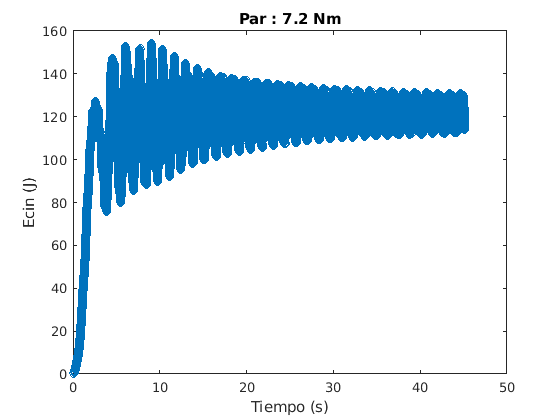

plot(vector_tiempo11,Ecin11,'o')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 7.2 Nm')

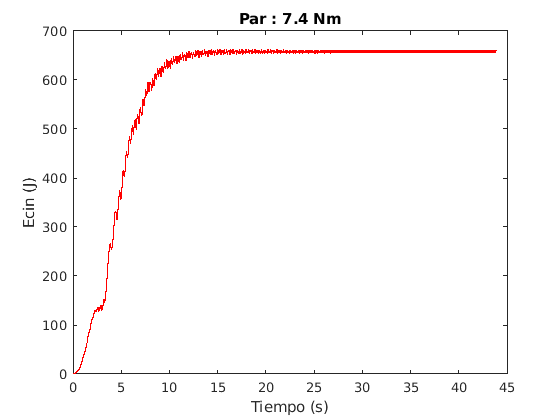

plot(vector_tiempo12,Ecin12,'r')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 7.4 Nm')

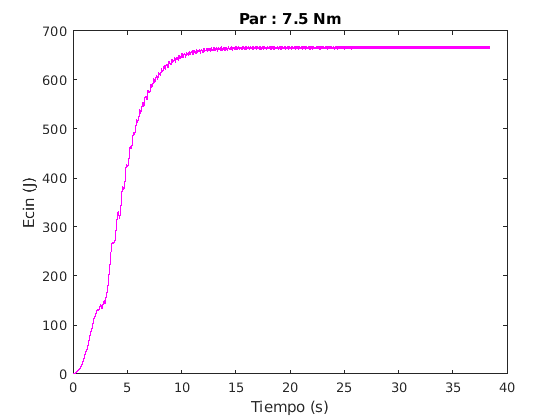

plot(vector_tiempo7,Ecin7,'m')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 7.5 Nm')

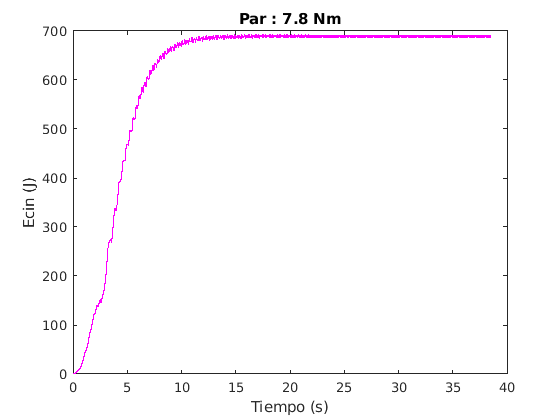

plot(vector_tiempo13,Ecin13,'m')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Par : 7.8 Nm')

## REPRESENTACIÓN DE ENERGÍAS POTENCIALES PARA TODAS LAS FRECUENCIAS

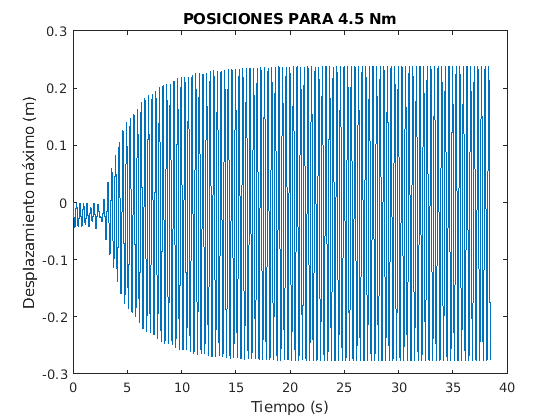

% Leemos los archivos procedentes de SOFA con los datos de las posiciones
% para las distintas frecuencias.

% Representamos primeros las posiciones en una grafica 2D
plot(vector_tiempo_4_5,posicion_0_4_5_(:,4))
title('POSICIONES PARA 4.5 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)')

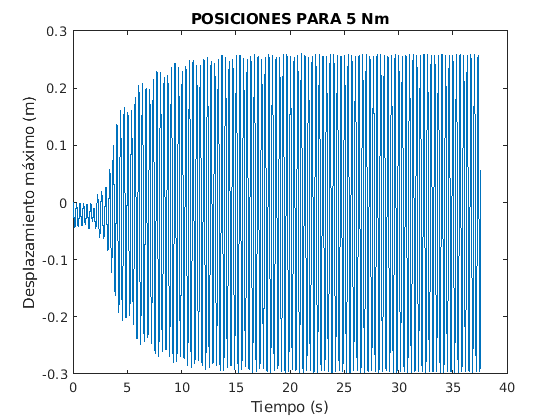


plot(vector_tiempo_5,posicion_0_5_(:,4))
title('POSICIONES PARA 5 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

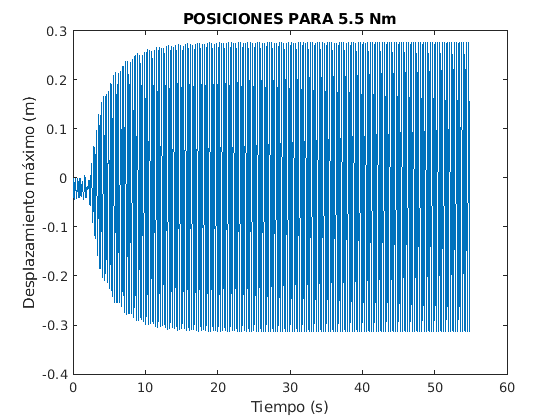


plot(vector_tiempo_5_5,posicion_0_5_5_(:,4))
title('POSICIONES PARA 5.5 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

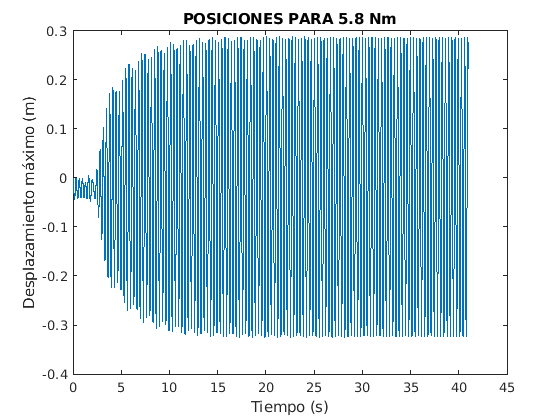


plot(vector_tiempo_5_8,posicion_0_5_8_(:,4))
title('POSICIONES PARA 5.8 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

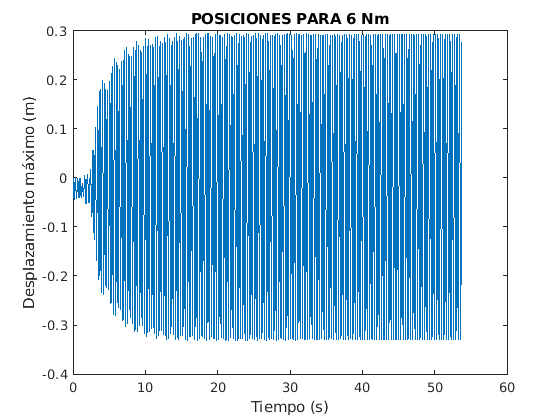


plot(vector_tiempo_6,posicion_0_6_(:,4))
title('POSICIONES PARA 6 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

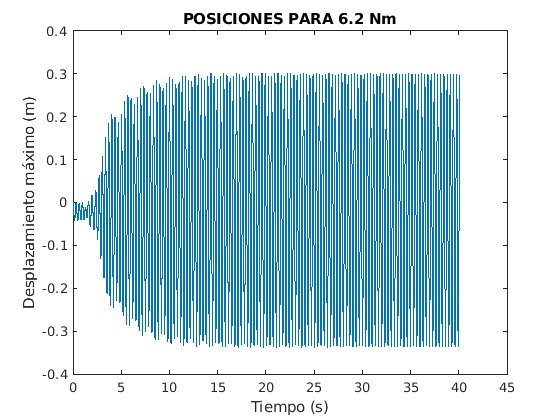


plot(vector_tiempo_6_2,posicion_0_6_2_(:,4))
title('POSICIONES PARA 6.2 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

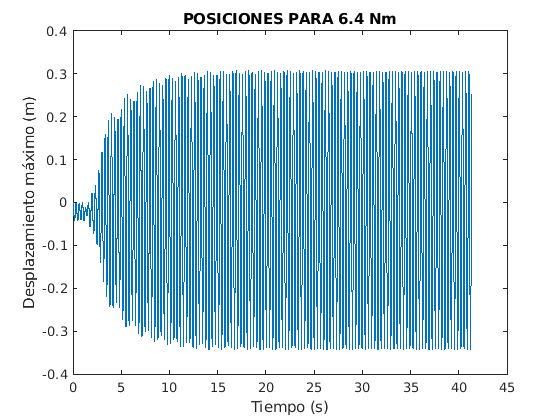


plot(vector_tiempo_6_4,posicion_0_6_4_(:,4))
title('POSICIONES PARA 6.4 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

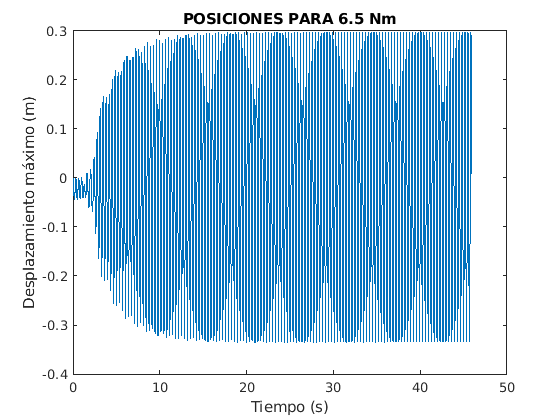


plot(vector_tiempo_6_5,posicion_0_6_5_(:,4))
title('POSICIONES PARA 6.5 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

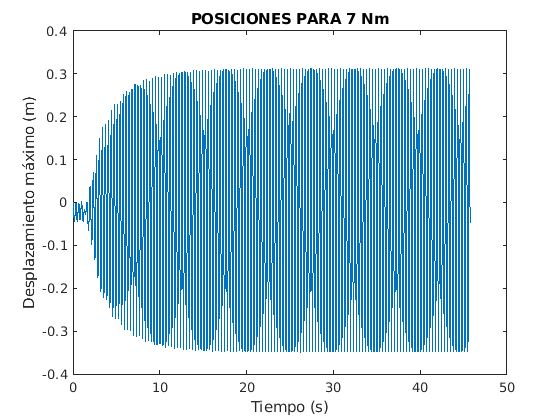


plot(vector_tiempo_7,posicion_0_7_(:,4))
title('POSICIONES PARA 7 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

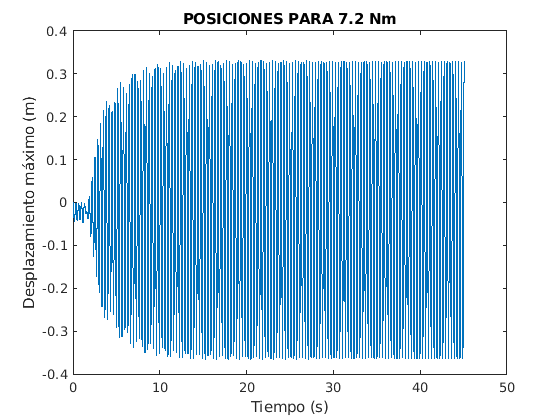


plot(vector_tiempo_7_2,posicion_0_7_2_(:,4))
title('POSICIONES PARA 7.2 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)')

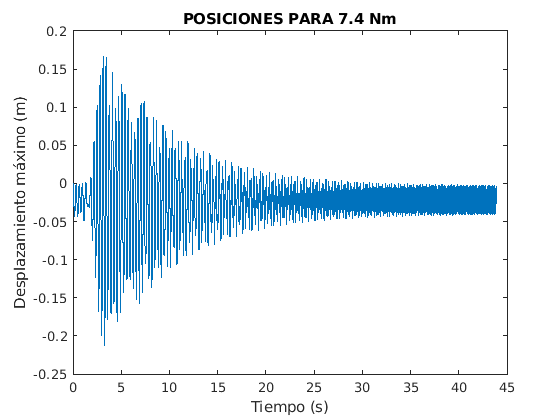


plot(vector_tiempo_7_4,posicion_0_7_4_(:,4))
title('POSICIONES PARA 7.4 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)')

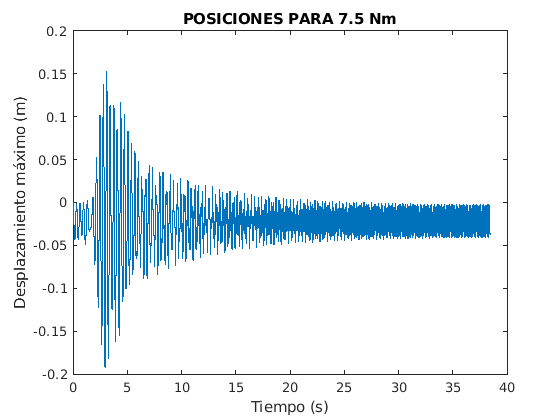


plot(vector_tiempo_7_5,posicion_0_7_5_(:,4))
title('POSICIONES PARA 7.5 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)')

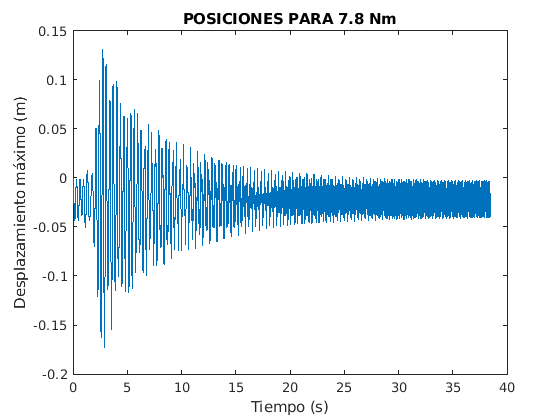


plot(vector_tiempo_7_8,posicion_0_7_8_(:,4))
title('POSICIONES PARA 7.8 Nm')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)')


% % Realizamos las representación de las distintas energías para cada
% % frecuencia estudiada
% n = 1
% for i=1:length(posicion_0_4_5_)
%     % Calculamos la energía potencial
%     Ep4_5(i) = 18.4339*0.5*(posicion_0_4_5_(i,3))^2;
%     if (vector_tiempo_4_5(i,1)>15.2)
%         % Almacenamos los valores estacionarios
%         Ep4_5_(i) = 18.4339*0.5*(posicion_0_4_5_(i,3))^2;
%         n = n + 1;
%     end
% end
% plot(vector_tiempo_4_5,Ep4_5)
% title('Energía potencial almacenada en la cadera con 4.5 Nm')
% xlabel('Tiempo (s)')
% ylabel('Energía (J)')
% n = 1;
% 
% for i=1:length(posicion_0_5_)
%     Ep5(i) = 18.4339*0.5*(posicion_0_5_(i,3))^2;
%     if (vector_tiempo_5(i,1)>16.1)
%         Ep5_(i) = 18.4339*0.5*(posicion_0_5_(i,3))^2;
%         n = n + 1;
%     end
% end
% plot(vector_tiempo_5,Ep5)
% title('Energía potencial almacenada en la cadera con 5 Nm')
% xlabel('Tiempo (s)')
% ylabel('Energía (J)')
% n = 1;
% 
% for i=1:length(posicion_0_5_5_)
%     Ep5_5(i) = 18.4339*0.5*(posicion_0_5_5_(i,3))^2;
%     if (vector_tiempo_5_5(i,1)>8.3)
%         Ep5_5_(i) = 18.4339*0.5*(posicion_0_5_5_(i,3))^2;
%         n = n + 1;
%     end
% end
% plot(vector_tiempo_5_5,Ep5_5)
% title('Energía potencial almacenada en la cadera con 5.5 Nm')
% xlabel('Tiempo (s)')
% ylabel('Energía (J)')
% n = 1;
% 
% for i=1:length(posicion_0_5_8_)
%     Ep5_8(i) = 18.4339*0.5*(posicion_0_5_8_(i,3))^2;
%     if (vector_tiempo_5_8(i,1)>60)
%         Ep5_8_(i) = 18.4339*0.5*(posicion_0_5_8_(i,3))^2;
%         n = n + 1;
%     end
% end
% plot(vector_tiempo_5_8,Ep5_8)
% title('Energía potencial almacenada en la cadera con 5.8 Nm')
% xlabel('Tiempo (s)')
% ylabel('Energía (J)')
% n = 1;
% 
% for i=1:length(posicion_0_6_)
%     Ep6(i) = 18.4339*0.5*(posicion_0_6_(i,3))^2;
%     if (vector_tiempo_6(i,1)>24)
%         Ep6_(i) = 18.4339*0.5*(posicion_0_6_(i,3))^2;
%         n = n + 1;
%     end
% end
% plot(vector_tiempo_6,Ep6)
% title('Energía potencial almacenada en la cadera con 6 Nm')
% xlabel('Tiempo (s)')
% ylabel('Energía (J)')
% n = 1;
% 
% for i=1:length(posicion_0_6_2_)
%     Ep6_2(i) = 18.4339*0.5*(posicion_0_6_2_(i,3))^2;
%     if (vector_tiempo_6_2(i,1)>80)
%         Ep6_2_(i) = 18.4339*0.5*(posicion_0_6_2_(i,3))^2;
%         n = n + 1;
%     end
% end
% plot(vector_tiempo_6_2,Ep6_2)
% title('Energía potencial almacenada en la cadera con 6.2 Nm')
% xlabel('Tiempo (s)')
% ylabel('Energía (J)')
% n=1
% 
% for i=1:length(posicion_0_6_4_)
%     Ep6_4(i) = 18.4339*0.5*(posicion_0_6_4_(i,3))^2;
%     if (vector_tiempo_6_4(i,1)>17.5)
%         Ep6_4_(i) = 18.4339*0.5*(posicion_0_6_4_(i,3))^2;
%         n = n + 1;
%     end
% end
% plot(vector_tiempo_6_4,Ep6_4)
% title('Energía potencial almacenada en la cadera con 6.4 Nm')
% xlabel('Tiempo (s)')
% ylabel('Energía (J)')
% n = 1;
% 
% for i=1:length(posicion_0_6_5_)
%     Ep6_5(i) = 18.4339*0.5*(posicion_0_6_5_(i,3))^2;
%     if (vector_tiempo_6_5(i,1)>11.5)
%         Ep6_5_(i) = 18.4339*0.5*(posicion_0_6_5_(i,3))^2;
%         n = n + 1;
%     end
% end
% plot(vector_tiempo_6_5,Ep6_5)
% title('Energía potencial almacenada en la cadera con 6.5 Nm')
% xlabel('Tiempo (s)')
% ylabel('Energía (J)')
% n = 1;
% 
% for i=1:length(posicion_0_7_)
%     Ep7(i) = 18.4339*0.5*(posicion_0_7_(i,3))^2;
%     if (vector_tiempo_7(i,1)>17.2)
%         Ep7_(n) = 18.4339*0.5*(posicion_0_7_(i,3))^2;
%         n = n + 1;
%     end
% end
% plot(vector_tiempo_7,Ep7)
% title('Energía potencial almacenada en la cadera con 7 Nm')
% xlabel('Tiempo (s)')
% ylabel('Energía (J)')
% n = 1;
% 
% for i=1:length(posicion_0_7_2_)
%     Ep7_2(i) = 18.4339*0.5*(posicion_0_7_2_(i,3))^2;
%     if (vector_tiempo_7_2(i,1)>40)
%         Ep7_2_(n) = 18.4339*0.5*(posicion_0_7_2_(i,3))^2;
%         n = n + 1;
%     end
% end
% plot(vector_tiempo_7_5,Ep7_5)
% title('Energía potencial almacenada en la cadera con 7.2 Nm')
% xlabel('Tiempo (s)')
% ylabel('Energía (J)')
% n = 1;
% 
% for i=1:length(posicion_0_7_4_)
%     Ep7_4(i) = 18.4339*0.5*(posicion_0_7_4_(i,3))^2;
%     if (vector_tiempo_7_4(i,1)>40)
%         Ep7_4_(n) = 18.4339*0.5*(posicion_0_7_4_(i,3))^2;
%         n = n + 1;
%     end
% end
% plot(vector_tiempo_7_4,Ep7_4)
% title('Energía potencial almacenada en la cadera con 7.4 Nm')
% xlabel('Tiempo (s)')
% ylabel('Energía (J)')
% n = 1;
% 
% for i=1:length(posicion_0_7_5_)
%     Ep7_5(i) = 18.4339*0.5*(posicion_0_7_5_(i,3))^2;
%     if (vector_tiempo_7_5(i,1)>40)
%         Ep7_5_(n) = 18.4339*0.5*(posicion_0_7_5_(i,3))^2;
%         n = n + 1;
%     end
% end
% plot(vector_tiempo_7_5,Ep7_5)
% title('Energía potencial almacenada en la cadera con 7.5 Nm')
% xlabel('Tiempo (s)')
% ylabel('Energía (J)')
% n = 1;
% 
% for i=1:length(posicion_0_7_8_)
%     Ep7_8(i) = 18.4339*0.5*(posicion_0_7_8_(i,3))^2;
%     if (vector_tiempo_7_8(i,1)>40)
%         Ep7_8_(n) = 18.4339*0.5*(posicion_0_7_8_(i,3))^2;
%         n = n + 1;
%     end
% end
% plot(vector_tiempo_7_8,Ep7_8)
% title('Energía potencial almacenada en la cadera con 7.8 Nm')
% xlabel('Tiempo (s)')
% ylabel('Energía (J)')
% n = 1;
% 
% % Hallamos el valor de RMS
% Ep4_5_rms = rms(Ep4_5_);
% Ep5_rms = rms(Ep5_);
% Ep5_5_rms = rms(Ep5_5_);
% Ep5_8_rms = rms(Ep5_8_);
% Ep6_rms = rms(Ep6_);
% Ep6_2_rms = rms(Ep6_2_);
% Ep6_4_rms = rms(Ep6_4_);
% Ep6_5_rms = rms(Ep6_5_);
% Ep7_rms = rms(Ep7_);
% Ep7_5_rms = rms(Ep7_5_);
% Ep7_8_rms = rms(Ep7_8_);
% 
% % Agrupamos los valores de energía potencial
% Ep_rms = [Ep4_5_rms, Ep5_rms, Ep5_5_rms, Ep5_8_rms, Ep6_rms, Ep6_2_rms, Ep6_4_rms, Ep6_5_rms, Ep7_rms, Ep7_5_rms Ep7_8_rms];
% 
% % Almacenamos los valores de frecuencias
% par = [4.5,5,5.5,5.8,6,6.2,6.4,6.5,7,7.5,7.8]';
% omega = [18.48 19.04];
% 
% % Aplicamos la reducción a 1 seg
% T = 2*pi./par;
% scale_to_seg = 1./T;
% Elastic_Energy = Ep_rms'.*scale_to_seg; % Energía usada en 1 seg
% 
% % Representamos la energía potencial escalada y lista para la comparación
% plot(omega,Elastic_Energy,'--bo',...
%     'LineWidth',3,...
%     'MarkerSize',10,...
%     'MarkerEdgeColor','b',...
%     'MarkerFaceColor',[0.5,0.5,0.5]);
% title('Energía elástica acumulada en la barra')
% xlabel('Frecuencia (rad/s)')
% ylabel('Energía elástica (J)')
% 
% plot(par,Elastic_Energy,'--bo',...
%     'LineWidth',3,...
%     'MarkerSize',10,...
%     'MarkerEdgeColor','b',...
%     'MarkerFaceColor',[0.5,0.5,0.5]);
% title('Energía elástica acumulada en la barra')
% xlabel('Par (Nm)')
% ylabel('Energía elástica (J)')